Definition of G(s)

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


G = 1 / ((s+1)*(0.5*s+1))

G =
 
           1
  -------------------
  0.5 s^2 + 1.5 s + 1
 
Continuous-time transfer function.
Model Properties


time vector

t = linspace(0, 6, 1000)

t =          0    0.0060    0.0120    0.0180    0.0240    0.0300    0.0360    0.0420    0.0480    0.0541    0.0601    0.0661    0.0721    0.0781    0.0841    0.0901    0.0961    0.1021    0.1081    0.1141    0.1201    0.1261    0.1321    0.1381    0.1441    0.1502    0.1562    0.1622    0.1682    0.1742    0.1802    0.1862    0.1922    0.1982    0.2042    0.2102    0.2162    0.2222    0.2282    0.2342    0.2402    0.2462    0.2523    0.2583    0.2643    0.2703    0.2763    0.2823    0.2883    0.2943


Step Response test

%step(G, t)
c1 = -10

c1 = -10

Gc1 = (-s+c1) / (c1*(s+1)*(0.5*s+1))

Gc1 =
 
       s + 10
  -----------------
  5 s^2 + 15 s + 10
 
Continuous-time transfer function.
Model Properties


%step(Gc1, t)
c2 = -0.25

c2 = -0.2500

Gc2 = (-s+c2) / (c2*(s+1)*(0.5*s+1))

Gc2 =
 
           s + 0.25
  --------------------------
  0.125 s^2 + 0.375 s + 0.25
 
Continuous-time transfer function.
Model Properties


%step(Gc2, t)
c3 = -0.1

c3 = -0.1000

Gc3 = (-s+c3) / (c3*(s+1)*(0.5*s+1))

Gc3 =
 
          s + 0.1
  -----------------------
  0.05 s^2 + 0.15 s + 0.1
 
Continuous-time transfer function.
Model Properties


%step(Gc3, t)
c4 = 0.1

c4 = 0.1000

Gc4 = (-s+c4) / (c4*(s+1)*(0.5*s+1))

Gc4 =
 
         -s + 0.1
  -----------------------
  0.05 s^2 + 0.15 s + 0.1
 
Continuous-time transfer function.
Model Properties


%step(Gc4, t)
c5 = 0.25

c5 = 0.2500

Gc5 = (-s+c5) / (c5*(s+1)*(0.5*s+1))

Gc5 =
 
          -s + 0.25
  --------------------------
  0.125 s^2 + 0.375 s + 0.25
 
Continuous-time transfer function.
Model Properties


%step(Gc5, t)
c6 = 10

c6 = 10

Gc6 = (-s+c6) / (c6*(s+1)*(0.5*s+1))

Gc6 =
 
       -s + 10
  -----------------
  5 s^2 + 15 s + 10
 
Continuous-time transfer function.
Model Properties


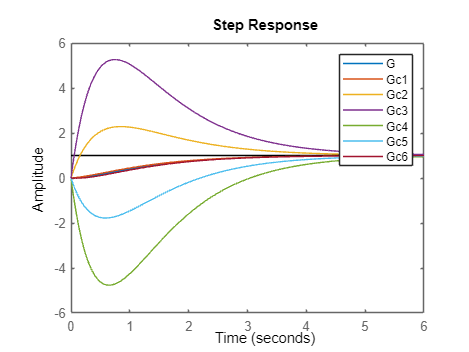

%step(Gc6, t)

step(G, Gc1, Gc2, Gc3, Gc4, Gc5, Gc6, t); grid on
legend('G', 'Gc1', 'Gc2', 'Gc3', 'Gc4', 'Gc5', 'Gc6')
grid off

sys = {G, Gc1, Gc2, Gc3, Gc4, Gc5, Gc6};
for k = 1:numel(sys)
    info(k) = stepinfo(sys{k});
end
struct2table(info)

ans = 7×9 table
    RiseTime    TransientTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak      PeakTime
    ________    _____________    ____________    ___________    ___________    _________    __________    _______    ________

      2.5901       4.6002           4.6002         0.90227        0.99917            0             0      0.99917     7.7827 
      2.5774       4.4951           4.4951          0.9035        0.99925            0             0      0.99925     7.7827 
     0.12212        5.448           5.7001         0.91574         2.2853       128.53             0       2.2853    0.82893 
    0.043058       5.3476           6.8014     

3.1.2

TODO

3.2.1

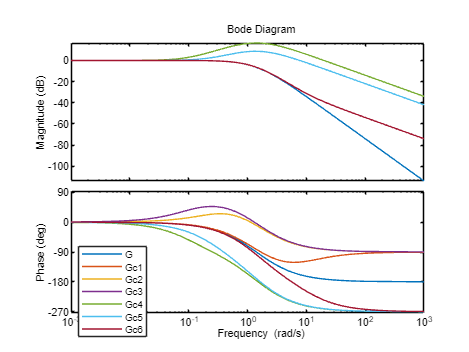

opts = bodeoptions;
opts.Grid = 'on';
opts.PhaseMatching = 'on';
opts.PhaseMatchingFreq = 0.0001;
opts.PhaseMatchingvalue = 0;
bode(G, Gc1, Gc2, Gc3, Gc4, Gc5, Gc6, opts); grid on
legend('G', 'Gc1', 'Gc2', 'Gc3', 'Gc4', 'Gc5', 'Gc6')
grid off